clear; close all;

## 0. Initialize Parameters

L = 1200; % Length of bridge
n = 1200; % Discretize into 1 mm seg. Do not change this value
P = 452; % Total weight of train [N]
x = linspace(0, L, n+1); % x-axis
%% 1. SFD, BMD under train loading
x_train = [52 228 392 568 732 908]; % Train Load Locations
train_length = 960 % Total length of train 

train_length = 960

% P_train = [1 1 1 1 1 1] * P/6;
P_train = [67.5 67.5 67.5 67.5 91 91]

P_train =    67.5000   67.5000   67.5000   67.5000   91.0000   91.0000


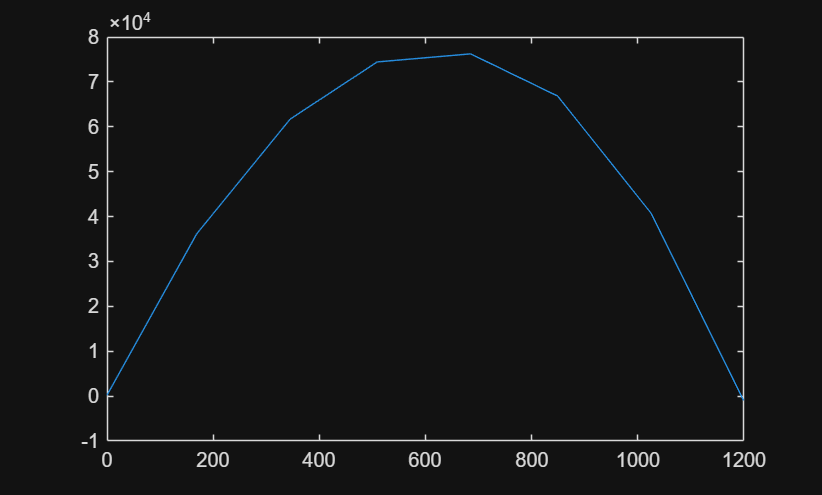

n_train = 1; % num of train locations
SFDi = zeros(n_train, n+1); % 1 SFD for each train loc.
BMDi = zeros(n_train, n+1); % 1 BMD for each train loc.
% Solve for SFD and BMD with the train at different locations
% train_start_locs = linspace(0, L - train_length, n_train) % all starting locations of the leftmost edge of the train
train_start_locs = [120];
% for i = 1:n_train
for i = 1:2
    train_start_loc = train_start_locs(1); % get current train starting location
    train_wheel_positions = x_train + train_start_loc;
    
    train_M_A = dot(train_wheel_positions,-P_train); % sum of moments of train loads at A, where A is leftmost side of bridge
    F_B = -train_M_A / L; % calculate F_B from sum_M_A = 0 = F_B * L - train_M_A

    sum_Fy = -sum(P_train); % sum of Fy eqn
    F_A = -sum_Fy - F_B;

    w = zeros(1, n+1); % construct applied loads. w(1) will hold the applied load at 0 mm, w(2) at 1 mm, etc. 
    w(1, 1) = F_A;
    w(1, end) = F_B;
    for wheel_num = 1:length(P_train) % add each train wheel load to applied load function
        w(1, round(train_wheel_positions(wheel_num)) - 1) = -P_train(wheel_num); % subtract one from index because w(1) = 0 mm
    end
    SFDi(i, :) = cumsum(w); % shear force diagram y values
    BMDi(i, :) = cumsum(SFDi(i, :)); % BMD y values
    % if i == 2
    %     figure;
    %     plot(x, SFDi)
    %     SFDi
    %     figure;
    %     plot(x, BMDi)
    % end
end
SFD = max(abs(SFDi)); % SFD envelope
BMD = max(BMDi); % BMD envelope
plot(x, BMD)

## 2. Define Bridge Parameters

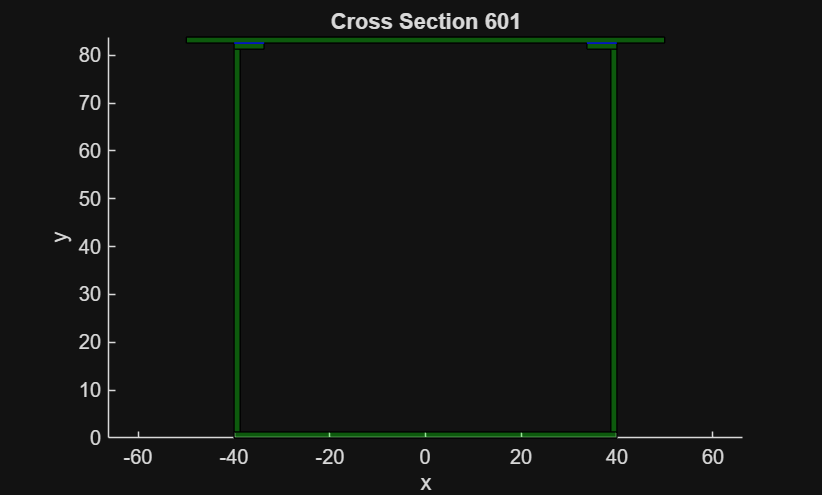

% first build the cross section template we want
% rectangles are numbered in the order they are attached to the template,
% starting with number 1
cs_template = CrossSectionTemplate(Rectangle(80, 1.27));
cs_template.attachRectangleAbove(Rectangle(1.27, 75 - 1.27 * 2), 1, @(curRect, refRect) refRect.x);
cs_template.attachRectangleBeside(Rectangle(1.27, 75 - 1.27 * 2), 1, @(curRect, refRect) refRect.x + refRect.w - curRect.w);
cs_template.attachRectangleAbove(Rectangle(1.27 + 5, 1.27), 2, @(curRect, refRect) refRect.x);
cs_template.attachRectangleBeside(Rectangle(1.27 + 5, 1.27), 3, @(curRect, refRect) refRect.x + refRect.w - curRect.w);
cs_template.attachRectangleAbove(Rectangle(100, 1.27), 0);

cs_template.attachGlue(GlueLine(6.27), 4, @(glueLine, refRect) refRect.x, ...
                                          @(glueLine, refRect) refRect.y + refRect.h, ...
                                          @(glueLine, refRect) glueLine.L);
cs_template.attachGlue(GlueLine(6.27), 5, @(glueLine, refRect) refRect.x, ...
                                          @(glueLine, refRect) refRect.y + refRect.h, ...
                                          @(glueLine, refRect) glueLine.L);

% first column is distance along beam. every set of two numbers following
% is the height, then width of rectangle number 1, 2, 3, ... n. If the number is
% -1 that means it doesn't change from the rectangle width and height
% specified in the template
param =[0   -1 -1 72.46 -1 72.46 -1 -1 -1 -1 -1 -1 -1;...
        400 -1 -1 80    -1 80    -1 -1 -1 -1 -1 -1 -1;...    
        800 -1 -1 80    -1 80    -1 -1 -1 -1 -1 -1 -1;...
        L   -1 -1 72.46 -1 72.46 -1 -1 -1 -1 -1 -1 -1];
%% NO MORE INPUTS REQUIRED

cs_params = zeros(length(x), size(param, 2) - 1); 
for column = 2:size(param, 2)
    cs_params(:, column - 1) = interp1(param(:,1), param(:,column), x); % linearly interpolate each parameter
end
cs = cell(length(x), 1); % cs{i} is the cross section at (i-1) mm along bridge length
cs_areas = zeros(length(x), 1); % cs(i) is the total area of the cross section at (i-1) mm along bridge length
for cur_x = x + 1
    cs{cur_x, 1} = CrossSection(cs_template, cs_params(cur_x, :));
    cs_areas(cur_x, 1) = cs{cur_x, 1}.getTotalArea();
end

rects = {length(x), length(cs_template.rectangles)}; % rects{i,j} holds Rectangle j of cross section i
rects_A = zeros(length(x), length(cs_template.rectangles));
rects_centroids = zeros(length(x), length(cs_template.rectangles)); % stores rectangle centroids relative to y = 0 (the bottom of the cross section)
glues = {length(x), length(cs_template.glueTabs)}; % glues{i,j} holds GlueLine j of cross section i

%initialize rects, rects_A, rects_centroids, and glues
for cs_num = 1:length(cs)
    cs_rects = cs{cs_num}.getRects();
    cs_glues = cs{cs_num}.getGlues();
    for rect_num = 1:length(cs_rects)
        cur_rect = cs_rects{rect_num};
        rects{cs_num, rect_num} = cur_rect;
        rects_A(cs_num, rect_num) = cur_rect.getArea();
        rects_centroids(cs_num, rect_num) = cur_rect.getCentroidY();
    end
    for glue_num = 1:length(cs_glues)
        glues{cs_num, glue_num} = cs_glues{glue_num};
    end
end


%%%% BUGFIXING AND RECTANGLE PRINTING
% for rect = 1:length(cs.getRects())
%     disp("RECT # "); disp(rect)
%     rects{rect}.printInfo()
% end

%% FOLLOWING IS PRINT CROSS SECTION CODE
figure; hold on; axis equal;

csLocation = 601;
rowRects = rects(csLocation,:);

for k = 1:numel(rowRects)
    R = rowRects{k};

    X = [R.x, R.x + R.w, R.x + R.w, R.x];
    Y = [R.y, R.y,       R.y + R.h, R.y + R.h];

    patch(X, Y, 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'k');
end

rowGlue = glues(csLocation, :);
for k = 1:numel(rowGlue)
    curGlue = rowGlue{k};
    plot([curGlue.x, (curGlue.x + curGlue.L)], [curGlue.y, curGlue.y], 'b')
end

xlabel('x'); ylabel('y');
title(sprintf('Cross Section %d', csLocation));
hold off;

%%%% END OF PRINTING STUFF


## 3. Calculate Sectional Properties

% ybar. location of centroidal axis from the bottom
ybar = sum(rects_A.*rects_centroids, 2)./cs_areas;
ybot = zeros(1201, 1);

getRectTopY = @(rect) rect.y + rect.h; % returns the y coordinate of the top line of a rectangle
ytop = cellfun(getRectTopY, rects(:, end)); % get the y coordinate of top rectangle in every cross section

% % I
getI = @(rect) rect.getRawI();
I = sum(rects_A.*(rects_centroids - ybar).^2, 2) + sum(cellfun(getI, rects), 2); % apply parallel axis theorem to get I
% Q at centroidal axes
Qcent = zeros(size(rects , 1), 1);
for cur_cs = 1:size(rects, 1)
    cur_ybar = ybar(cur_cs);
    Qcent(cur_cs, 1) = sum(cellfun(@(r) r.getQ(cur_ybar, cur_ybar), rects(cur_cs,:)));
end


% Q at glue location
Qglue = zeros(size(glues)); % Qglue(i, j) is the Q for glue j at cross section i
for cur_cs = 1:size(Qglue, 1)
    cur_ybar = ybar(cur_cs);
    for cur_glue = 1:size(Qglue, 2)
       glue_y = glues{cur_glue}.y; % height of the glue
       Qglue(cur_cs, cur_glue) = sum(cellfun(@(r) r.getQ(glue_y, cur_ybar), rects(cur_cs,:)));
    end
end

## 4. Calculate Applied Stress

S_top = -BMD'.*(ytop - ybar)./I
S_bot = BMD'.*(ybar - ybot)./I

S_tens = zeros(size(S_top));
S_comp = zeros(size(S_bot));
for i = 1:length(S_top)
    cur_S_top = S_top(i);
    cur_S_bot = S_bot(i);
    if cur_S_top >= 0
        S_tens(i) = cur_S_top;
        S_comp(i) = cur_S_bot;
    else
        S_comp(i) = cur_S_top;
        S_tens(i) = cur_S_bot;
    end
end
S_tens
S_comp

%calculating T_cent
totalWidthAtCentroid = zeros(length(cs), 1);
for cs_num = 1:length(cs)
    cur_ybar = ybar(cs_num);
    totalWidthAtCentroid(cs_num) = cs{cs_num}.totalWidthAtY(cur_ybar);
end
T_cent = SFD'.*Qcent./I./totalWidthAtCentroid;

glue_num = 0;
glueLayers = cellfun(@(cs) cs.getGlueLayers(), cs, 'UniformOutput', false);
num_glue_layers = size(glueLayers{1}, 1);
T_glue = zeros(length(cs), num_glue_layers); % T_glue(i, j) will hold the T_glue for glue layer j at cross section i
glue_layer_widths = zeros(length(cs), num_glue_layers);
glue_layer_Q = zeros(length(cs), num_glue_layers); %glue_layer_Q(i, j) will hold the Q value for glue layer j at cross section i

for cs_num = 1:length(cs)
    cur_glue_cs = glueLayers{cs_num}; % get the glue layers cell matrix for this cross section
    glue_num = 0;
    for glue_layer_num = 1:size(cur_glue_cs, 1)
        cur_glue_layer = cur_glue_cs(glue_layer_num, :); % get the current layer of glue
        total_glue_layer_width = 0;
        for cur_tab_num_in_layer = 1:size(cur_glue_layer, 2)
            total_glue_layer_width = total_glue_layer_width + cur_glue_layer{1, cur_tab_num_in_layer}.L;
            glue_num = glue_num + 1;
        end
        glue_layer_Q(cs_num, glue_layer_num) = Qglue(cs_num, glue_num);
        T_glue(cs_num, glue_layer_num) = SFD(cs_num)*Qglue(cs_num, glue_num) / I(cs_num) / total_glue_layer_width;
        glue_layer_widths(cs_num, glue_layer_num) = total_glue_layer_width;
    end

end
T_glue %be careful if there are multiple layers?
glue_layer_widths
glue_layer_Q

%% 5. Material and Thin Plate Buckling Capacities
E = 4000; % MPa
mu = 0.2; % Poisson's Ratio
Smax_tens = 30; % MPa 
Smax_comp = 6; % MPa
T_max = 4; % MPa
T_gmax = 2; % MPa
% S_buck1 = 4*pi^2*E/(12*(1-mu^2)).*()
% S_buck2 = 0.425*pi^2*E/(12*(1-mu^2))*()
% S_buck3 =
% T_buck =

%% 6. FOS
FOS_tens = min(Smax_tens./S_tens);
FOS_comp = min(Smax_comp./abs(S_comp));
FOS_shear = min(T_max./abs(T_cent));
FOS_glue = min(T_gmax./abs(T_glue));
% FOS_buck1 =
% FOS_buck2 =
% FOS_buck3 =
% FOS_buckV =

## 7. Min FOS and the failure load Pfail

% minFOS = min(FOS_tens, FOS_comp, FOS_shear) %add more 
% Pf = minFOS * P

## 8. Vfail and Mfail

%Mf for tens and comp assume that compression occurs on top and tension on
%bottom. Mf = moment failure?
Mf_tens = Smax_tens./(ybar - ybot).*I;
Mf_comp = Smax_comp./(ybar - ybot).*I;

plot(x, Mf_tens);
hold on
plot(x, Mf_comp);
plot(x, BMD');
legend('Matboard Tension Failure', 'Matboard Compression Failure', 'BMD')
hold off

Vf_shear = T_max.*I.*totalWidthAtCentroid./Qcent;
plot(x, Vf_shear)
hold on
Vf_glue = min((T_gmax.*I.*glue_layer_widths./glue_layer_Q), [], 2)
plot(x, Vf_glue)
plot(x, SFD)

% Mf_buck1 =
% Mf_buck2 =
% Mf_buck3 =
% Vf_buckV =

## 9. Output plots of Vfail and Mfail

% subplot(2,3,1)
% hold on; grid on; grid minor;
% plot(x, Vf_shear, 'r')
% plot(x, -Vf_shear.* SFD', 'r')
% plot(x, SFDi, 'k');
% plot([0, L], [0, 0], 'k', 'LineWidth', 2)
% legend('Matboard Shear Failure')
% xlabel('Distance along bridge (mm)')
% ylabel('Shear Force (N)')